# Two-lens system: Lee's equation

clear

% Define the symbolic variables representing the focal lengths of the lenses, 
% the distances between the object and the first lens (z1), between the two lenses (z12), 
% and the undetermined image distance (z2u). Also define the ray height and angle at the starting point.
syms f1 f2 z1 z2u z12 x1 theta1 positive  

% Define the starting ray vector
r1 = [x1 theta1]'

$$r1 = \left(\begin{array}{c} x_{1}\\ \theta_{1} \end{array}\right)$$


% Calculate the ray vector at the undetermined z2u by multiplying RTMs 
% from the starting point 
r2 = [1 z2u; 0 1] * [1 0; -1/f2 1] * [1 z12; 0 1] * [1 0; -1/f1 1] * [1 z1; 0 1] * r1

$$r2 = \begin{array}{l} \left(\begin{array}{c} -\theta_{1}\,\left(z_{1}\,\sigma_{1}-\mathrm{z2u}+z_{12}\,\left(\frac{\mathrm{z2u}}{f_{2}}-1\right)\right)-x_{1}\,\sigma_{1}\\ \theta_{1}\,\left(z_{1}\,\left(\frac{\frac{z_{12}}{f_{2}}-1}{f_{1}}-\frac{1}{f_{2}}\right)-\frac{z_{12}}{f_{2}}+1\right)+x_{1}\,\left(\frac{\frac{z_{12}}{f_{2}}-1}{f_{1}}-\frac{1}{f_{2}}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\mathrm{z2u}}{f_{2}}+\frac{\mathrm{z2u}-z_{12}\,\left(\frac{\mathrm{z2u}}{f_{2}}-1\right)}{f_{1}}-1 \end{array}$$


% Determine the condition for focusing at z2, which occurs when the x-component of r2 
% is independent of theta1 (the initial angle of the ray)
x2 = collect(r2(1), theta1)

$$x2 = \left(\mathrm{z2u}-z_{1}\,\left(\frac{\mathrm{z2u}}{f_{2}}+\frac{\mathrm{z2u}-z_{12}\,\left(\frac{\mathrm{z2u}}{f_{2}}-1\right)}{f_{1}}-1\right)-z_{12}\,\left(\frac{\mathrm{z2u}}{f_{2}}-1\right)\right)\,\theta_{1}-x_{1}\,\left(\frac{\mathrm{z2u}}{f_{2}}+\frac{\mathrm{z2u}-z_{12}\,\left(\frac{\mathrm{z2u}}{f_{2}}-1\right)}{f_{1}}-1\right)$$

x20 = subs(r2(1), theta1, 0)

$$x20 = -x_{1}\,\left(\frac{\mathrm{z2u}}{f_{2}}+\frac{\mathrm{z2u}-z_{12}\,\left(\frac{\mathrm{z2u}}{f_{2}}-1\right)}{f_{1}}-1\right)$$

z2 = solve(x2==x20, z2u)

$$z2 = \frac{f_{1}\,f_{2}\,z_{1}+f_{1}\,f_{2}\,z_{12}-f_{2}\,z_{1}\,z_{12}}{f_{1}\,z_{1}-f_{1}\,f_{2}+f_{2}\,z_{1}+f_{1}\,z_{12}-z_{1}\,z_{12}}$$


% Check the validity of the solution by verifying that when z1 equals f1, z2 equals f2
subs(z2, z1, f1)

$$ans = f_{2}$$


% Calculate the magnification by finding the ratio of the final and initial x-components of the ray
x2 = simplify(subs(r2(1), z2u, z2))

$$x2 = -\frac{f_{1}\,f_{2}\,x_{1}}{f_{1}\,z_{1}-f_{1}\,f_{2}+f_{2}\,z_{1}+f_{1}\,z_{12}-z_{1}\,z_{12}}$$

m = x2 / x1

$$m = -\frac{f_{1}\,f_{2}}{f_{1}\,z_{1}-f_{1}\,f_{2}+f_{2}\,z_{1}+f_{1}\,z_{12}-z_{1}\,z_{12}}$$


% Check the validity of the magnification by verifying that when z1 equals f1, 
% the magnification equals -f2/f1
subs(m, z1, f1)

$$ans = -\frac{f_{2}}{f_{1}}$$

## Introduce $\alpha=\frac{z_1}{f_1} - 1$ 

A simple case first: when z12 = f1 + f2

syms alpha 

% delta_z2f / z2f as a function of alpha
z2_temp = collect(simplify(subs(z2, z12, f1+f2)), z1)

$$z2\_temp = \left(-\frac{{f_{2}}^{2}}{{f_{1}}^{2}}\right)\,z_{1}+\frac{f_{2}\,\left({f_{1}}^{2}+f_{2}\,f_{1}\right)}{{f_{1}}^{2}}$$

z2_alpha = collect(simplify(subs(z2_temp, z1, f1*(1+alpha))), alpha)  % z2f as a function of alpha

$$z2\_alpha = \left(-\frac{{f_{2}}^{2}}{f_{1}}\right)\,\alpha +f_{2}$$

dz2_alpha = simplify(z2_alpha/f2 - 1)  % delta_z2f / z2f due to alpha

$$dz2\_alpha = -\frac{\alpha \,f_{2}}{f_{1}}$$


% new m
m_alpha = simplify(subs(m, z12, f1+f2))

$$m\_alpha = -\frac{f_{2}}{f_{1}}$$

    % always -f2/f1

## Introduce $\beta=\frac{z_{12}}{f_1+f_2}-1$

syms beta  % fractional change in z12 relative to f1+f2

% Calculate the deviation in z2 (relative to f2) as a function of alpha and beta
z2_temp = collect(simplify(subs(z2, z12, (f1+f2)*(1+beta))), beta)

$$z2\_temp = \frac{\left({f_{1}}^{2}\,f_{2}+f_{1}\,{f_{2}}^{2}-z_{1}\,f_{1}\,f_{2}-z_{1}\,{f_{2}}^{2}\right)\,\beta +{f_{1}}^{2}\,f_{2}+f_{1}\,{f_{2}}^{2}-z_{1}\,{f_{2}}^{2}}{\left(f_{1}\,f_{2}-f_{1}\,z_{1}-f_{2}\,z_{1}+{f_{1}}^{2}\right)\,\beta +{f_{1}}^{2}}$$

z2_alpha_beta = collect(collect(simplify(subs(z2_temp, z1, f1*(1+alpha))), beta), alpha)

$$z2\_alpha\_beta = \frac{\left(\beta \,{f_{2}}^{2}+{f_{2}}^{2}+\beta \,f_{1}\,f_{2}\right)\,\alpha -f_{1}\,f_{2}}{\left(\beta \,f_{1}+\beta \,f_{2}\right)\,\alpha -f_{1}}$$

dz2_alpha_beta = simplify(z2_alpha_beta/f2 - 1)

$$dz2\_alpha\_beta = \frac{\alpha \,f_{2}}{\alpha \,\beta \,f_{1}-f_{1}+\alpha \,\beta \,f_{2}}$$


% Try to further simplify it
dz2_alpha_beta = 1 / collect(collect(1/dz2_alpha_beta*alpha*f2, beta), alpha) * alpha*f2

$$dz2\_alpha\_beta = \frac{\alpha \,f_{2}}{\left(\beta \,\left(f_{1}+f_{2}\right)\right)\,\alpha -f_{1}}$$


% Calculate the magnification as a function of alpha and beta
m_temp = collect(simplify(subs(m, z12, (f1+f2)*(1+beta))), beta)

$$m\_temp = \frac{-f_{1}\,f_{2}}{\left(f_{1}\,f_{2}-f_{1}\,z_{1}-f_{2}\,z_{1}+{f_{1}}^{2}\right)\,\beta +{f_{1}}^{2}}$$

m_alpha_beta = simplify(subs(m_temp, z1, f1*(1+alpha)))

$$m\_alpha\_beta = \frac{f_{2}}{\alpha \,\beta \,f_{1}-f_{1}+\alpha \,\beta \,f_{2}}$$


% Try to further simplify it
m_alpha_beta = 1 / collect(collect(1/m_alpha_beta*f2, beta), alpha) * f2

$$m\_alpha\_beta = \frac{f_{2}}{\left(\beta \,\left(f_{1}+f_{2}\right)\right)\,\alpha -f_{1}}$$


% Introduce m0 as -f2/f1 and express the magnification and deviation in z2 in terms of m0
syms m0  % -f2/f1
m_alpha_beta = simplify(collect(subs(m_alpha_beta, f2, -m0*f1), alpha))

$$m\_alpha\_beta = \frac{m_{0}}{\left(\beta \,m_{0}-\beta \right)\,\alpha +1}$$


% relative magnification (m/m0)
rm_alpha_beta = m_alpha_beta / m0  

$$rm\_alpha\_beta = \frac{1}{\left(\beta \,m_{0}-\beta \right)\,\alpha +1}$$


% relative z2f deviation (delta_z2f / z2f) using m0
dz2_alpha_beta = simplify(collect(subs(dz2_alpha_beta, f2, -m0*f1), alpha))

$$dz2\_alpha\_beta = \frac{m_{0}\,\alpha }{\left(\beta \,m_{0}-\beta \right)\,\alpha +1}$$

## Evaluate the effects of $\alpha$ and $\beta$.

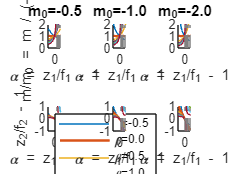

m0s = [-0.5, -1, -2];  % Different values of m0 to investigate
a = [-0.5 0.5];  % Range of alpha values for symbolic computation
b = [-0.5, 0, 0.5, 1, 1.5, 2, 3];  % Different values of beta to investigate

nm = numel(m0s);  % Number of m0 values
figure;
clr = lines;  % Get a set of distinguishable colors for the plots

% Loop over all m0 values to plot the relative deviation in z2 and the relative magnification for each beta value
for im = 1:nm
    m01 = m0s(im);  % the current m0
    for ib = 1:numel(b)
        b1 = b(ib);  % the current beta value

        % Plot the relative magnification as a function of alpha for the current beta value
        subplot(2, nm, im);
        hold on;
        l = fplot(subs(rm_alpha_beta, [m0 beta], [m01 b1]), a);
        l.Color = clr(ib,:);
        if b1 == 0,  l.LineWidth = 1.5;  end
        if im == 1,  ylabel("m/m_0 = m / (-f_2/f_1)");  end
        title(sprintf("m_0=%.1f", m01));

        % Plot the relative deviation in z2 as a function of alpha for the current beta value
        subplot(2, nm, nm+im);
        hold on;
        l = fplot(subs(dz2_alpha_beta, [m0 beta], [m01 b1]), a);
        l.Color = clr(ib,:);
        if b1 == 0,  l.LineWidth = 1.5;  end
        if im == 1,  ylabel("z_2/f_2 - 1");  end

    end
end    

% Add legend and labels to the plots
subplot(2, nm, nm+1);
legend(compose("\\beta=%.1f", b), 'Location', 'southwest');
for im = 1:nm
    subplot(2, nm, im);
    axis image;
    ylim([0 2]);
    xlabel("\alpha = z_1/f_1 - 1");

    subplot(2, nm, nm+im);
    axis image;
    ylim([-1 1]);
    xlabel("\alpha = z_1/f_1 - 1");
end

## Example

In the context of fundus' ring illumination, we aim to position the image 10% before the focal plane (z2/f2 - 1 = -0.1). For beta values greater than 0, we find the corresponding alpha and magnification values and observe how they vary with beta.

m01 = -1;  % Set m0 to -1 for this example
nb = numel(b);
a1 = zeros(nb, 1);  % Array to store the calculated alpha values
m1 = zeros(nb, 1);  % Array to store the calculated magnification values

% Loop over all beta values to calculate the corresponding alpha and magnification values
for ib = 1:nb
    b1 = b(ib);
    a1(ib) = solve(subs(dz2_alpha_beta, [m0 beta], [m01 b1]) == -0.1, alpha);
    m1(ib) = subs(subs(rm_alpha_beta, [m0 beta], [m01 b1]), alpha, a1(ib));
end

% Display the beta values along with the corresponding alpha and magnification values
[b(:), a1, m1]

ans =    -0.5000    0.1111    0.9000
         0    0.1000    1.0000
    0.5000    0.0909    1.1000
    1.0000    0.0833    1.2000
    1.5000    0.0769    1.3000
    2.0000    0.0714    1.4000
    3.0000    0.0625    1.6000
